# **Macroeconometrics project: When does monetary policy matter ? Policy Stance vs Term Premium News**

# **Giovanni Manche & Timothée Dangleterre**

### Link of the paper**: **https://www.banque-france.fr/en/publications-and-statistics/publications/when-does-monetary-policy-matter-policy-stance-vs-term-premium-news

clc; clear; clear all; 

## First part: Standard effects of Monetary Policy Surprises

### FOMC announcements between 1989 and 2022

% Import of FOMC MPS (Bauer and Swanson dataset)
dataset_mps = readtable("Data/FOMC surprises.xlsx", "Sheet","FOMC (update 2023)");


% Import of Target and Path surprises (Acosta, Brennan and Jacobson
% dataset)
dataset_gss = readtable("Data/ABJ-2024-monetary-policy-surprises.xlsx", "Sheet","Data");

% We restrain our period over 1999 - 2022
indic_data = dataset_gss.date > '01-Jan-1999' & dataset_gss.date < '01-Jan-2023';
disp("Number of FOMC announcements over this sample")

Number of FOMC announcements over this sample


disp(sum(indic_data))

   191



Over 1999 - 2022 (period of reference in the paper) we have 191 FOMC announcements against 188 in the paper. We keep all of them for further analysis.

% We keep the dataset of MPS on the backtest dates
indic_data_mps = dataset_mps.Date > '01-Jan-1999' & dataset_mps.Date < '01-Jan-2023';
dataset_mps_backtest = dataset_mps(indic_data_mps, :);
% We only keep the scheduled FOMC meeting
indic_scheduled = dataset_mps_backtest.Unscheduled == 0;
dataset_mps_backtest = dataset_mps_backtest(indic_scheduled,:);

% Similarly, we filter the GSS dataset 
dataset_gss_backtest = dataset_gss(indic_data,:);

% We check that both periods are similar
verif_dates = dataset_mps_backtest.Date == dataset_gss_backtest.date;
if sum(verif_dates) ~= length(dataset_gss_backtest.date)
    error("There should be the same number of dates within each dataset");
end

% We construct a table with dates, MPS (adjusted to news), target and path
mps_base = table(dataset_gss_backtest.date, dataset_mps_backtest.MPS_ORTH, ...
    dataset_gss_backtest.GSS_target, dataset_gss_backtest.GSS_path);
mps_base.Properties.VariableNames = ["Dates", "MPS", "Target", "Path"];

% If there are missing values for adjusted to news MPS, we replace the
% missing values by the unadjusted MPS
mps_base.MPS(isnan(mps_base.MPS)) = dataset_mps_backtest.MPS(isnan(mps_base.MPS));
disp(mps_base)

       Dates           MPS          Target          Path   
    ___________    ___________    ___________    __________

    03-Feb-1999     -0.0079836      0.0022439      0.021133
    30-Mar-1999      -0.037075     -0.0054446     -0.036117
    18-May-1999        0.10977      -0.012947        0.3113
    30-Jun-1999      -0.096252      -0.050714      -0.15049
    24-Aug-1999      -0.022146       0.052805     -0.085808
    05-Oct-1999       0.085046      -0.038946       0.23973
    16-Nov-1999       0.056967       0.097804      0.038215
    21-Dec-1999       0.020012     -0.0042199       0.10663
    02-Feb-2000      -0.024186      -0.041907        0.0961
    21-Mar-2000      0.0027249     -0.0022292      0.024409
    16-May-2000       0.043024       0.053371      0.034569
    28-Jun-2000      -0.024633      -0.010289     -0.030649
    22-Aug-2000       0

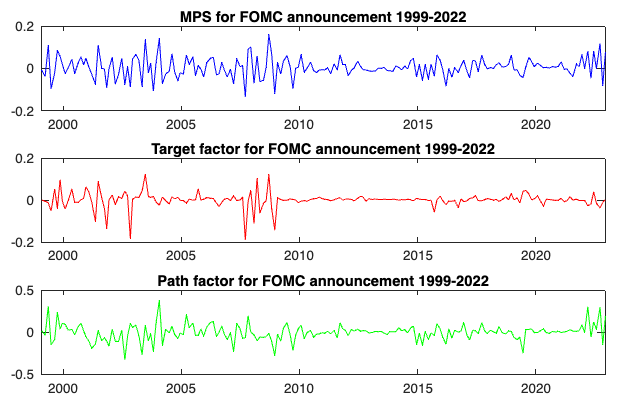



% Graph
f0 = figure("Units","normalized","Position",[0,0,1,1]);
t = tiledlayout(3,1,'Padding','compact','TileSpacing','compact');
nexttile();
plot(mps_base.Dates, mps_base.MPS,'b');title("MPS for FOMC announcement 1999-2022");
nexttile();
plot(mps_base.Dates, mps_base.Target,'r');title("Target factor for FOMC announcement 1999-2022");
nexttile();
plot(mps_base.Dates, mps_base.Path, 'g');title("Path factor for FOMC announcement 1999-2022");

We retrieve the daily changes following these announcements for the following assets:

- S&P 500

- 2, 5 and 10 years maturity ZC bond yields (GSS dataset)

### Market data import and returns calculation

#### SP500 Data

% Import SP500 price and compute daily log returns (source: Yahoo Finance)
dataset_sp500 = readtable("Data/sp500 daily.xlsx");

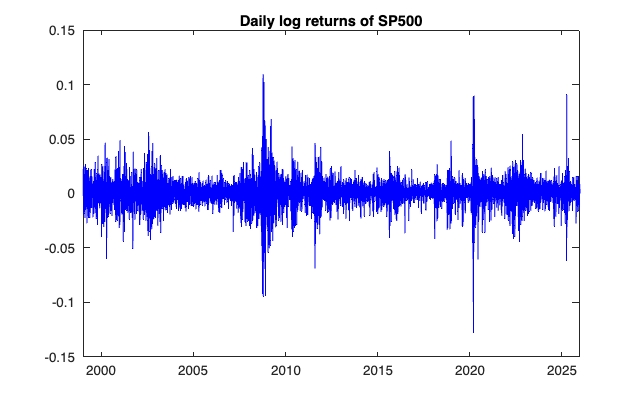

sp500_ret = diff(log(dataset_sp500.GSPC_Close),1);
sp500_base = table(dataset_sp500.index_GSPC_(2:length(dataset_sp500.index_GSPC_)), ...
    sp500_ret, 'VariableNames',{'Dates','Returns'});

% Graph
f1 = figure("Units","normalized","Position",[0,0,1,1]);
plot(sp500_base.Dates, sp500_base.Returns, 'b');title("Daily log returns of SP500");


% We filter to only keep the dates of interest
match_dates_sp = ismember(sp500_base.Dates, mps_base.Dates);
sp500_base = sp500_base(match_dates_sp,:);

#### ZC Bond yields data

% Import Gurkaynak, Sack and Wright data (available from Fed website)
dataset_gsw = readtable("Data/feds200628.xlsx");
dataset_gsw.Date = datetime(dataset_gsw.Date, 'InputFormat', 'yyyy-MM-dd');

% Keep only values for 2, 5 and 10 year on from 1999-2022
dataset_yields = dataset_gsw(dataset_gsw.Date > '01-Jan-1999' & dataset_gsw.Date < '01-Jan-2023', ...
    ["Date", "SVENY02","SVENY05","SVENY10"]);

% Compute the daily change in nominal yields and keep the matching dates
diff_yield = diff(dataset_yields(:,2:size(dataset_yields.Properties.VariableNames,2)),1);
yield_base = table(dataset_yields.Date(2:length(dataset_yields.Date)), ...
    diff_yield.SVENY02, diff_yield.SVENY05, diff_yield.SVENY10...
    , 'VariableNames',{'Dates','2y','5y','10y'});

% Graph
f2 = figure("Units","normalized","Position",[0 0 1 1])

f2 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 1 1]
       Units: 'normalized'

  Show all properties


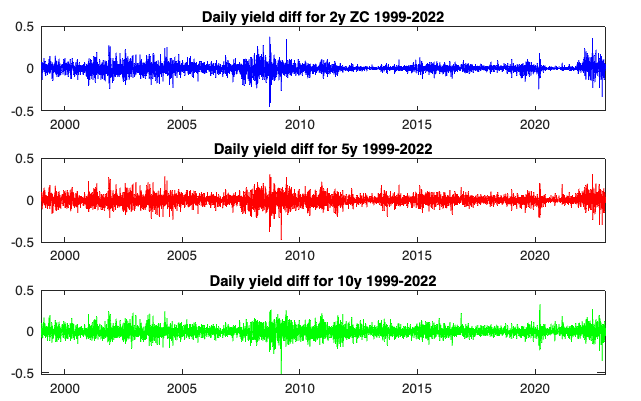

t = tiledlayout(3,1,'Padding','compact','TileSpacing','compact');
nexttile();
plot(yield_base.Dates, yield_base.("2y"),'b');title("Daily yield diff for 2y ZC 1999-2022");
nexttile();
plot(yield_base.Dates, yield_base.("5y"),'r');title("Daily yield diff for 5y 1999-2022");
nexttile();
plot(yield_base.Dates, yield_base.("10y"), 'g');title("Daily yield diff for 10y 1999-2022");


% We filter to only keep the dates of interest
match_dates_yield = ismember(yield_base.Dates,  mps_base.Dates);
yield_base = yield_base(match_dates_yield,:);

Now we conduct the following regressions:

- 
$$\Delta Y_t = \alpha + \beta_{MPS} . MPS_t + \varepsilon_t$$


- 
$$\Delta y_t = \alpha + \beta_t . Target_t + \beta_P . Path_t + \varepsilon_t$$


With $\Delta y_t$ the daily change in a given asset price or ZC nominal interest rates on 2,5 and 10 year maturities.

% We prepare the output to retrieve (Table 1 in the paper)
rowNames = {'MPS', 'se_mps','R2_reg1','Obs', ...
    'Target', 'se_target','Path', 'se_path','R2_reg2'};
colNames = {'S&P 500','2y','5y','10y'};
table1 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

% We define the elements for the regression
const = ones(numel(mps_base.MPS),1);
Xmps = [const mps_base.MPS];
Xtp = [const mps_base.Target mps_base.Path];

% Financial assets to regress against both MPS and Path/Target factors
% (normalize by 100)
yvec_assets = [sp500_base.Returns*100, yield_base.("2y"), yield_base.("5y"), yield_base.("10y")];

% Loop over both type of regression 
for i=1:2
    % First regression: against MPS
    if i == 1
        X = Xmps;
    else
        X = Xtp;
    end

    % Loop over all assets  
    for j = 1:size(yvec_assets,2)
        % Perform the regression
        [coef_reg, r_2] = regression(yvec_assets(:,j), X);

        % retrieve the results
        if i == 1
            vec_results = [table2array(coef_reg(2,1)) table2array(coef_reg(2,2))...
                r_2 length(X)];
            table1{1:4,j} = round(vec_results',3);
            
        else
            vec_results = [table2array(coef_reg(2,1)) table2array(coef_reg(2,2))...
                table2array(coef_reg(3,1)) table2array(coef_reg(3,2)) r_2];
            table1{5:9,j} = round(vec_results',3);
        end
    end
end


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0077  -0.0155 
 x2 | -0.0155   3.3372 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0076 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0001 
 x2 | -0.0001   0.0117 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0001 
 x2 | -0.0001   0.0109 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient 


disp(table1)

                 S&P 500     2y       5y       10y 
                 _______    _____    _____    _____

    MPS          -4.607     0.642    0.552    0.306
    se_mps        1.827     0.087    0.108    0.104
    R2_reg1       0.033     0.224    0.121    0.044
    Obs             191       191      191      191
    Target       -5.007     0.331    0.179    0.043
    se_target     2.395     0.109    0.138    0.135
    Path         -1.752     0.341    0.317    0.204
    se_path       0.891     0.041    0.051     0.05
    R2_reg2       0.041     0.296    0.174    0.081



This table presents the standard monetary policy effects on stock prices and ZC bond yields (Table 1 in the paper). Overall, the results we obtain are close from those presented in the paper, except for robust SE who can be a bit different (especially for S&P 500) but it doesn't change the overall result. 

% We perform a significativity test
rowNames_signi = {'pval MPS','pval Target','pvalPath'};
table_signi = array2table(nan(numel(rowNames_signi), numel(colNames)), ...
                'RowNames', rowNames_signi, ...
                'VariableNames', colNames);
table_signi{1, :} = round(2*(1-normcdf(abs(table1{"MPS",:}./table1{"se_mps",:}))),3);
table_signi{2,:} = round(2*(1-normcdf(abs(table1{"Target",:}./table1{"se_target",:}))),3);
table_signi{3,:} = round(2*(1-normcdf(abs(table1{"Path",:}./table1{"se_path",:}))),3);
disp(table_signi)

                   S&P 500     2y       5y       10y 
                   _______    _____    _____    _____

    pval MPS        0.012         0        0    0.003
    pval Target     0.037     0.002    0.195     0.75
    pvalPath        0.049         0        0        0



Compared to the paper:

- The coefficient associated with the S&P 500 is always found to be significative at 5\%

- With the MPS regression, all the coefficients associated with the yield are found to be significative at the 0.01 threshold

- With the path / target regression: target is only significative for the 2 year ZC, while Path is highly significative for all ZC.

Similarly to what the authors note, the r-squared explain only a small fraction of the variance of these asset prices, even though FOMC should be the main market moover of bond yields.

## Second part: Target and Path surprises do not discriminate future policy

% compute total MPS (Gurkaynak et al)
mps_base.TotalMPS = mps_base.Target+mps_base.Path;

% Retrieve the response of assets (FF1, ED1, ED2, ED3, ED4) 
yvec_futures = [dataset_mps_backtest.ED1 dataset_mps_backtest.ED2 ...
    dataset_mps_backtest.ED3 dataset_mps_backtest.ED4];

### Regression on MPS

rowNames = {'2se_up', '1se_up','MPS','1se_down', ...
    '2se_down'};
colNames = {'ED1','ED2','ED3','ED4'};
table_mps_bauer = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);
table_mps_gurkaynak = table_mps_bauer;

% Regression vector with the Total MPS from Gurkaynak et al (2005)
Xgss = [const mps_base.TotalMPS];

% Loop over all configurations
for i = 1:2
    % In one case, we use the new-adjusted MPS of Bauer and Swanson, in the
    % other we use the MPS of Gurkaynak et al
    if i == 1
        X = Xmps;
    else
        X = Xgss;
    end

    % Loop over all prices changes in asset
    for j = 1:size(yvec_futures,2)
        % Regression
        [coef_reg, r_2] = regression(yvec_futures(:,j), X);

        % Compute the CI
        quantile = norminv([0.9 0.95], 0, 1);
        ic = compute_ic(table2array(coef_reg(2,1)), table2array(coef_reg(2,2)), length(X));
        
        % report in the table
        if i == 1
            table_mps_bauer{:,j} = round(ic, 3)';
        else
            table_mps_gurkaynak{:,j} = round(ic, 3)';
        end
    end
end


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0015 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0012 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0017 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0026 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient 

Results are really far from the authors. Potential source of errors:

- Nature of the data used ? FF1, ED1, ED2, ED3, ED4 correspond to changes over a 30 minute window in our setup, not the change over the day

- Main pb besides: Total MPS from Gurkaynak et al is far from Bauer and Swanson one

- CI not computed correctly (maybe simply coef +- 1 se or 2 se?)

### Regression on Path and Factors

rowNames = {'2se_up', '1se_up','MPS','1se_down', ...
    '2se_down'};
colNames = {'ED1','ED2','ED3','ED4'};
table_target = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);
table_path = table_target;

% Loop over all configurations
for i = 1:2
    % In one case, we regress over the Path factor while the regressor over
    % the target factor in the other
    if i == 1
        X = [Xtp(:,1),Xtp(:,2)];
    else
        X = [Xtp(:,1),Xtp(:,3)];
    end

    % Loop over all prices changes in asset
    for j = 1:size(yvec_futures,2)
        % Regression
        [coef_reg, r_2] = regression(yvec_futures(:,j), X);

        % Compute the CI
        quantile = norminv([0.9 0.95], 0, 1);
        ic = compute_ic(table2array(coef_reg(2,1)), table2array(coef_reg(2,2)), length(X));
        
        % report in the table
        if i == 1
            table_target{:,j} = round(ic, 3)';
        else
            table_path{:,j} = round(ic, 3)';
        end
    end
end


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0034 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0068 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0108 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0140 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient 

For target, the results are pretty close (even though different) to the paper. However for path, they are really off. Considering that we had really close results with the standard MP results, the main problem is probably the change of asset price used (should use daily response, not intraday response).

To check

## Classification of monetary policy announcements: policy stance vs HOM

% Retrieve the MP classification: announcements with opposite Path and
% Target factors sign, HOM and Attenuation
[indic_opp, indic_att, indic_hom] = classifier_mp_events(mps_base);

% Descriptive statistics for monetary surprises
opp_sign_mps = mps_base(indic_opp, :);
same_sign_mps = mps_base(indic_opp==0, :);

% Table for descriptive statistics result (Table 3 of the paper)
rowNames = {'Same Signs','Opposite Signs'};
colNames = {'N','%','Mean','Mean Abs','SD'};
table3 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

table3{1,:} = [length(same_sign_mps.MPS) 100*round(length(same_sign_mps.MPS)/length(mps_base.MPS),0) ...
    round(mean(same_sign_mps.MPS),3) round(mean(abs(same_sign_mps.MPS)),3) round(std(same_sign_mps.MPS),3)];
table3{2,:} = [length(opp_sign_mps.MPS) 100*round(length(opp_sign_mps.MPS)/length(mps_base.MPS),0) ...
    round(mean(opp_sign_mps.MPS),3) round(mean(abs(opp_sign_mps.MPS)),3) round(std(opp_sign_mps.MPS),3)];
disp(table3)

                       N      %     Mean     Mean Abs     SD  
                      ___    ___    _____    ________    _____

    Same Signs         90      0    0.004     0.038       0.05
    Opposite Signs    101    100    0.005     0.032      0.046



Again, the results are really close from the paper (except for the standard deviation which is slightly higher).

We look at the monetary policy effects with same or opposite signs:

### Monetary policy effects with same or opposite signs

% We add the interaction term between MPS and the dummy in the MPS base
mps_base.interaction = mps_base.MPS .* indic_opp;

% Table to present the results
rowNames = {'MPS','se_mps', 'MPS x 1opp', 'se_interaction', '1opp', 'se_opp','R2','Obs'};
colNames = {'S&P 500','2y','5y','10y'};
table2 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

% Regressors matrix
X = [const mps_base.MPS mps_base.interaction indic_opp];

% Loop for the regression
for j = 1:size(yvec_assets,2)

    % Regression
    [coef_reg, r_2] = regression(yvec_assets(:,j),X);

    % Retrieve the results
    results = [table2array(coef_reg(2,1:2)) table2array(coef_reg(3,1:2)) ...
        table2array(coef_reg(4,1:2)) r_2 size(yvec_assets,1)];
    table2{:,j} = round(results', 3);
end


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0160  -0.0247   0.0247  -0.0160 
 x2 | -0.0247   6.5316  -6.5316   0.0247 
 x3 |  0.0247  -6.5316  13.2035  -0.0607 
 x4 | -0.0160   0.0247  -0.0607   0.0304 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0000  -0.0001   0.0001  -0.0000 
 x2 | -0.0001   0.0144  -0.0144   0.0001 
 x3 |  0.0001  -0.0144   0.0292  -0.0001 
 x4 | -0.0000   0.0001  -0.0001   0.0001 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0001  -0.0001   0.0001  -


% Display the results
disp(table2);

                      S&P 500     2y        5y       10y  
                      _______    _____    ______    ______

    MPS               -7.544     0.395      0.29     0.066
    se_mps             2.556      0.12      0.15     0.146
    MPS x 1opp          5.86     0.496      0.53     0.487
    se_interaction     3.634     0.171     0.214     0.207
    1opp                0.19     0.004    -0.004    -0.003
    se_opp             0.174     0.008      0.01      0.01
    R2                 0.054     0.259     0.149     0.071
    Obs                  191       191       191       191



Function to compute the result table directly (testing block)

% Test
% Table to present the results
rowNames = {'MPS','se_mps', 'MPS x 1opp', 'se_interaction','R2'};
colNames = {'S&P 500','2y','5y','10y'};
table_test = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

table_test = table_results(yvec_assets, X, table_test,[2,3]);


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0160  -0.0247   0.0247  -0.0160 
 x2 | -0.0247   6.5316  -6.5316   0.0247 
 x3 |  0.0247  -6.5316  13.2035  -0.0607 
 x4 | -0.0160   0.0247  -0.0607   0.0304 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0000  -0.0001   0.0001  -0.0000 
 x2 | -0.0001   0.0144  -0.0144   0.0001 
 x3 |  0.0001  -0.0144   0.0292  -0.0001 
 x4 | -0.0000   0.0001  -0.0001   0.0001 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0001  -0.0001   0.0001  -

disp(table_test);

                      S&P 500     2y       5y       10y 
                      _______    _____    _____    _____

    MPS               -7.544     0.395     0.29    0.066
    se_mps             2.556      0.12     0.15    0.146
    MPS x 1opp          5.86     0.496     0.53    0.487
    se_interaction     3.634     0.171    0.214    0.207
    R2                 0.054     0.259    0.149    0.071



Function to compute the ME and the associated SE and put it in a table (test)

rowNames = {'MPS|1^opp = 1','se'};
colNames = {'S&P 500','2y','5y','10y'};
table_test_me = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);
% vector with the coefficients to compute the desired ME
coefs_me = [2 3];
table_test_me = me_results(yvec_assets, X, table_test_me, coefs_me);


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0160  -0.0247   0.0247  -0.0160 
 x2 | -0.0247   6.5316  -6.5316   0.0247 
 x3 |  0.0247  -6.5316  13.2035  -0.0607 
 x4 | -0.0160   0.0247  -0.0607   0.0304 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0000  -0.0001   0.0001  -0.0000 
 x2 | -0.0001   0.0144  -0.0144   0.0001 
 x3 |  0.0001  -0.0144   0.0292  -0.0001 
 x4 | -0.0000   0.0001  -0.0001   0.0001 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4   
-----------------------------------------
 x1 |  0.0001  -0.0001   0.0001  -

disp(table_test_me);

                     S&P 500     2y       5y       10y 
                     _______    _____    _____    _____

    MPS|1^opp = 1    -1.684     0.891     0.82    0.553
    se                2.583     0.121    0.152    0.147




% Merge both result tables to get table2
table2_test = [table_test;table_test_me];
disp(table2_test);

                      S&P 500     2y       5y       10y 
                      _______    _____    _____    _____

    MPS               -7.544     0.395     0.29    0.066
    se_mps             2.556      0.12     0.15    0.146
    MPS x 1opp          5.86     0.496     0.53    0.487
    se_interaction     3.634     0.171    0.214    0.207
    R2                 0.054     0.259    0.149    0.071
    MPS|1^opp = 1     -1.684     0.891     0.82    0.553
    se                 2.583     0.121    0.152    0.147



Functions to use to compute further table results, the function "me_results" only works for 1 marginal effect/se pair computation. Create a table for each marginal effect needed. 

Can perform significativity check (cf supra)

### Monetary policy transmission with higher-order moment signals

We test the heterogenous effects of monetary surprises on asset prices based on the following specification:

- 
$$\Delta y_t = \alpha + \beta_1 . MPS_t + \beta_2 . MPS_t . \mathbf{1}_t^{Att} + \beta_3 . MPS_t . \mathbf{1}_t^{HOM} + \beta_4 . \mathbf{1}_t^{Att} + \beta_5 . \mathbf{1}_t^{HOM} + \varepsilon_t$$


% Add the interactions term in the base
mps_base.mpsAtt = mps_base.MPS .* indic_att;
mps_base.mpsHom = mps_base.MPS .* indic_hom;

% Build the regression matrix
X = [const mps_base.MPS mps_base.mpsAtt mps_base.mpsHom ...
    indic_att indic_hom];

% Result tables (1 for each average affect and the main one)
rowNames = {'MPS','se_mps', 'MPS x 1att', 'se_mpsAtt', ...
    'MPS x 1hom','se_mpsHom','R2'};
colNames = {'S&P 500','2y','5y','10y'};
table4 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

rowNames = {'MPS|1^att = 1','se_me_att'};
table_me_att = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

rowNames = {'MPS|1^hom = 1','se_me_hom'};
table_me_hom = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

% Coefficients to plot in the table 4 (MPS and both interactions terms)
coefs_to_retrieve = [2 3 4];

% Regression and 
table4 = table_results(yvec_assets, X, table4,coefs_to_retrieve);


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4       x5       x6   
-----------------------------------------------------------
 x1 |  0.0160  -0.0247   0.0247   0.0247  -0.0160  -0.0160 
 x2 | -0.0247   6.5263  -6.5263  -6.5263   0.0247   0.0247 
 x3 |  0.0247  -6.5263  43.9373   6.5263  -0.6129  -0.0247 
 x4 |  0.0247  -6.5263   6.5263  14.7190  -0.0247  -0.0552 
 x5 | -0.0160   0.0247  -0.6129  -0.0247   0.1275   0.0160 
 x6 | -0.0160   0.0247  -0.0247  -0.0552   0.0160   0.0326 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4       x5       x6   
-----------------------------------------------------------
 x1 |  0.0000  -0.0001   0.0001   0.0001  -0.0000  -0.0000 
 x2 | -0.0001   0.0142  -0.0142  -0.0142   0.0001   0.0001 
 x3 |  0.0001  -0.0142   0.0

disp(table4);

                  S&P 500     2y        5y       10y 
                  _______    _____    ______    _____

    MPS           -7.544     0.395      0.29    0.066
    se_mps         2.555     0.119     0.149    0.145
    MPS x 1att    13.492      0.14    -0.012    -0.04
    se_mpsAtt      6.629     0.309     0.388    0.377
    MPS x 1hom     4.349     0.549     0.627    0.595
    se_mpsHom      3.837     0.179     0.224    0.218
    R2             0.064      0.28     0.169    0.086



The results for the main regression are close to the one of the paper. Main differences:

- MPS x 1att: negative for the 5y ZC nominal yield while it should be positive

- SE different (same results as before, might be due to hac function not compute the same SE - "Huber-White heteroskedasticity-robust se").

We add the results for the ME 

% Computation of the ME and se associated for attenuating statements
coefs_me = [2 3];
table_me_att = me_results(yvec_assets, X, table_me_att, coefs_me);


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4       x5       x6   
-----------------------------------------------------------
 x1 |  0.0160  -0.0247   0.0247   0.0247  -0.0160  -0.0160 
 x2 | -0.0247   6.5263  -6.5263  -6.5263   0.0247   0.0247 
 x3 |  0.0247  -6.5263  43.9373   6.5263  -0.6129  -0.0247 
 x4 |  0.0247  -6.5263   6.5263  14.7190  -0.0247  -0.0552 
 x5 | -0.0160   0.0247  -0.6129  -0.0247   0.1275   0.0160 
 x6 | -0.0160   0.0247  -0.0247  -0.0552   0.0160   0.0326 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4       x5       x6   
-----------------------------------------------------------
 x1 |  0.0000  -0.0001   0.0001   0.0001  -0.0000  -0.0000 
 x2 | -0.0001   0.0142  -0.0142  -0.0142   0.0001   0.0001 
 x3 |  0.0001  -0.0142   0.0


% Computation of the ME and se associated for HOM statements
coefs_me = [2 4];
table_me_hom = me_results(yvec_assets, X, table_me_hom, coefs_me);


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4       x5       x6   
-----------------------------------------------------------
 x1 |  0.0160  -0.0247   0.0247   0.0247  -0.0160  -0.0160 
 x2 | -0.0247   6.5263  -6.5263  -6.5263   0.0247   0.0247 
 x3 |  0.0247  -6.5263  43.9373   6.5263  -0.6129  -0.0247 
 x4 |  0.0247  -6.5263   6.5263  14.7190  -0.0247  -0.0552 
 x5 | -0.0160   0.0247  -0.6129  -0.0247   0.1275   0.0160 
 x6 | -0.0160   0.0247  -0.0247  -0.0552   0.0160   0.0326 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2       x3       x4       x5       x6   
-----------------------------------------------------------
 x1 |  0.0000  -0.0001   0.0001   0.0001  -0.0000  -0.0000 
 x2 | -0.0001   0.0142  -0.0142  -0.0142   0.0001   0.0001 
 x3 |  0.0001  -0.0142   0.0


% Merge both result tables to get table2
table4 = [table4;table_me_att;table_me_hom];
disp(table4);

                     S&P 500     2y        5y       10y 
                     _______    _____    ______    _____

    MPS              -7.544     0.395      0.29    0.066
    se_mps            2.555     0.119     0.149    0.145
    MPS x 1att       13.492      0.14    -0.012    -0.04
    se_mpsAtt         6.629     0.309     0.388    0.377
    MPS x 1hom        4.349     0.549     0.627    0.595
    se_mpsHom         3.837     0.179     0.224    0.218
    R2                0.064      0.28     0.169    0.086
    MPS|1^att = 1     5.948     0.535     0.278    0.026
    se_me_att         6.116     0.285     0.358    0.348
    MPS|1^hom = 1    -3.195     0.944     0.918    0.661
    

The results are pretty close for the ME effect of HOM statements. It is less precise in the case of ATT statements.

% Regressor matrix for each subsample regression
X = [const mps_base.MPS];

% We build a table to store the R2 over Same sign statements, 
% ATT statements and HOM statements
rowNames = {'R2','R2 Same Sign','R2 Att', 'R2 HOM'};
table_r2 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

table_r2{'R2',:} = round(table4{'R2',:},2);

% 1 - computation of R2 for Same sign statements
vect_r2 = subsample_r_squared(yvec_assets, X, [1-indic_opp]);


Estimator type: HC
Estimation method: CLM
Effective sample size: 90
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0155  -0.0239 
 x2 | -0.0239   6.3235 

Estimator type: HC
Estimation method: CLM
Effective sample size: 90
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0001 
 x2 | -0.0001   0.0167 

Estimator type: HC
Estimation method: CLM
Effective sample size: 90
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0001 
 x2 | -0.0001   0.0187 

Estimator type: HC
Estimation method: CLM
Effective sample size: 90
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0001 
 x2 | -0.0001   0.0146 


table_r2{'R2 Same Sign',:} = round(vect_r2,2);

% 2 - computation of R2 for Attenuation statements
vect_r2 = subsample_r_squared(yvec_assets, X, indic_att);


Estimator type: HC
Estimation method: CLM
Effective sample size: 14
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.1956  -1.0322 
 x2 | -1.0322  65.6488 

Estimator type: HC
Estimation method: CLM
Effective sample size: 14
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0004  -0.0021 
 x2 | -0.0021   0.1331 

Estimator type: HC
Estimation method: CLM
Effective sample size: 14
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0005  -0.0026 
 x2 | -0.0026   0.1669 

Estimator type: HC
Estimation method: CLM
Effective sample size: 14
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0004  -0.0022 
 x2 | -0.0022   0.1429 


table_r2{'R2 Att',:} = round(vect_r2,2);

% 3 - computation of R2 for HOM statements
vect_r2 = subsample_r_squared(yvec_assets, X, indic_hom);


Estimator type: HC
Estimation method: CLM
Effective sample size: 87
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0153  -0.0282 
 x2 | -0.0282   7.5832 

Estimator type: HC
Estimation method: CLM
Effective sample size: 87
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0000  -0.0000 
 x2 | -0.0000   0.0129 

Estimator type: HC
Estimation method: CLM
Effective sample size: 87
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0001  -0.0001 
 x2 | -0.0001   0.0315 

Estimator type: HC
Estimation method: CLM
Effective sample size: 87
Small sample correction: off

Coefficient Covariances:

    |    x1       x2   
-----------------------
 x1 |  0.0001  -0.0001 
 x2 | -0.0001   0.0342 


table_r2{'R2 HOM',:} = round(vect_r2,2);

% We print the final table result
table4('R2',:) = [];
table4 = [table4; table_r2];
disp(table4);

                     S&P 500     2y        5y       10y 
                     _______    _____    ______    _____

    MPS              -7.544     0.395      0.29    0.066
    se_mps            2.555     0.119     0.149    0.145
    MPS x 1att       13.492      0.14    -0.012    -0.04
    se_mpsAtt         6.629     0.309     0.388    0.377
    MPS x 1hom        4.349     0.549     0.627    0.595
    se_mpsHom         3.837     0.179     0.224    0.218
    MPS|1^att = 1     5.948     0.535     0.278    0.026
    se_me_att         6.116     0.285     0.358    0.348
    MPS|1^hom = 1    -3.195     0.944     0.918    0.661
    se_me_hom         2.862     0.133     0.167    0.163
    

#### Effet of HOM statements on interest rates depending on the maturity

% We retrieve values for the 1 to 15y, and 20, 25 and 30 year maturity
nominal_yields_base = dataset_gsw(dataset_gsw.Date > '01-Jan-1999' & dataset_gsw.Date < '01-Jan-2023', ...
    ["Date", "SVENY01", "SVENY02", ...
    "SVENY03", "SVENY04", "SVENY05", "SVENY06", ...
    "SVENY07", "SVENY08", "SVENY09", "SVENY10", ...
    "SVENY11", "SVENY12", "SVENY13", "SVENY14", "SVENY15", ...
    "SVENY20","SVENY25","SVENY30"]);

% If there are missing values, we forward fill
nominal_yields_base = fillmissing(nominal_yields_base, 'previous');

% We filter to only keep the dates of interest
match_dates_yield = ismember(nominal_yields_base.Date,  mps_base.Dates);
nominal_yields_base = nominal_yields_base(match_dates_yield,:);

Objective of this block of code: retrieve the nominal ZC yield for maturity 1 to 15 and 20, 25, 30 from the GSW dataset. Once retrieved, we match the dates with the MPS.

% Result tables (1 for each average affect and the main one)
rowNames = {'MPS','se_mps', 'MPS x 1hom', 'se_mpsHom', 'R2'};
colNames = {'1y','2y','3y','4y','5y',...
    '6y','7y','8y','9y','10y','11y','12y','13y',...
    '14y','15y','20y','25y','30y'};
table5 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

rowNames = {'MPS|1^hom = 1','se_me_hom'};
table_me_hom = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);

% Build the regression matrix
y = table2array(nominal_yields_base(:,2:size(nominal_yields_base,2)));
X = [const mps_base.MPS mps_base.mpsAtt mps_base.mpsHom ...
    indic_att indic_hom];

% Coefficients to plot in the table 4 (MPS interaction with HOM)
coefs_to_retrieve = [2 4];

% Regression and 
table5 = table_results(y, X, table5,coefs_to_retrieve);


Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2        x3        x4        x5       x6   
--------------------------------------------------------------
 x1 |  0.0398   -0.0615    0.0615    0.0615  -0.0398  -0.0398 
 x2 | -0.0615   16.2533  -16.2533  -16.2533   0.0615   0.0615 
 x3 |  0.0615  -16.2533  109.4232   16.2533  -1.5265  -0.0615 
 x4 |  0.0615  -16.2533   16.2533   36.6567  -0.0615  -0.1374 
 x5 | -0.0398    0.0615   -1.5265   -0.0615   0.3174   0.0398 
 x6 | -0.0398    0.0615   -0.0615   -0.1374   0.0398   0.0811 

Estimator type: HC
Estimation method: CLM
Effective sample size: 191
Small sample correction: off

Coefficient Covariances:

    |    x1       x2        x3        x4        x5       x6   
--------------------------------------------------------------
 x1 |  0.0366   -0.0565    0.0565    0.0565  -0.0366  -0.0366 
 x2 | -0.0565   14.9206  -14.9206  -14.9206   0.0565   

disp(table5);

                    1y        2y        3y        4y       5y        6y        7y        8y        9y       10y       11y       12y       13y       14y       15y       20y       25y       30y  
                  ______    ______    ______    ______    _____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______


Not the good regressors, maybe diff one or other. To check + add R2 table at the end (cf supra)